clearvars;
[cry, FS] = audioread("crying_beeps.wav");

Afficher le signal

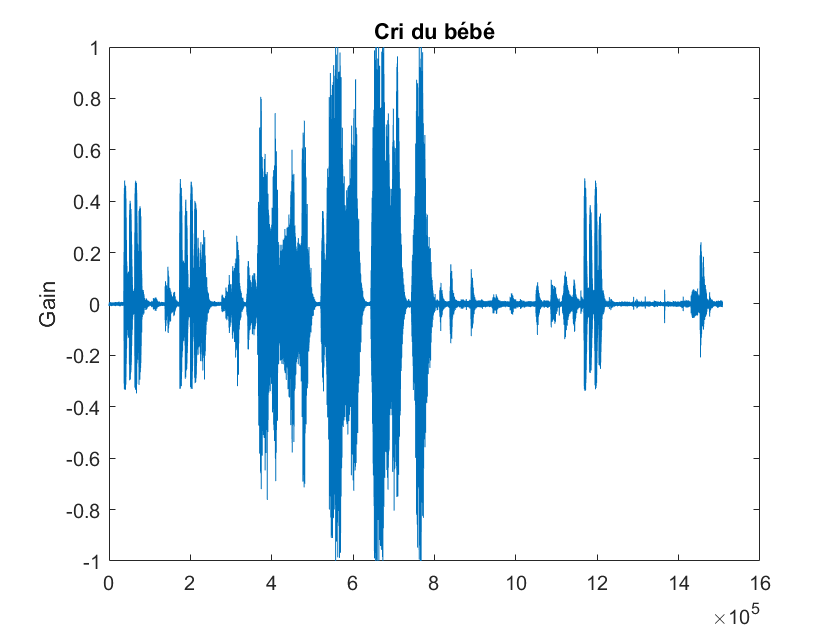

subplot(1, 1, 1); plot(cry); 
ylabel("Gain");
title("Cri du bébé");

Segmentation

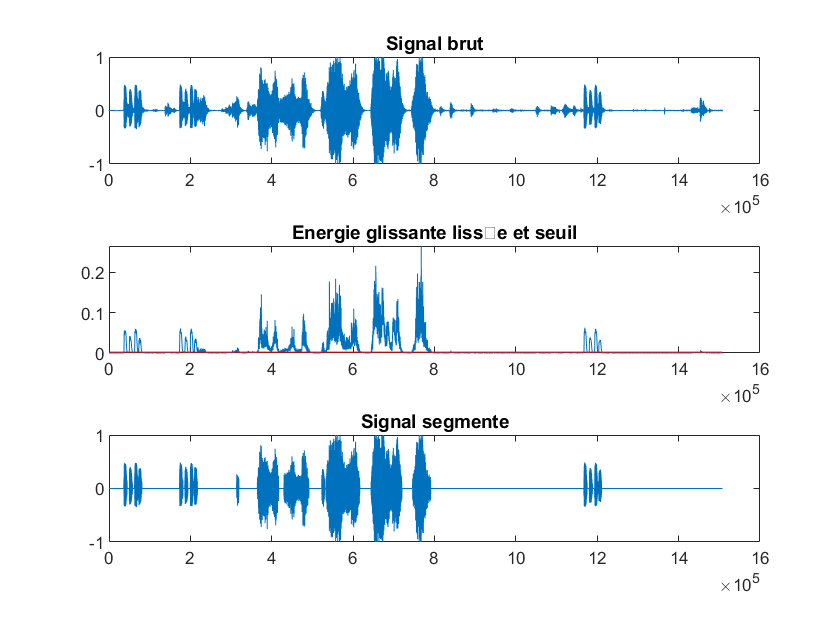

[signal_sortie_segmentation_energie_glissante, vecteur_logique] = segmentation_energie_glissante(cry, FS, 30, 0.0021);

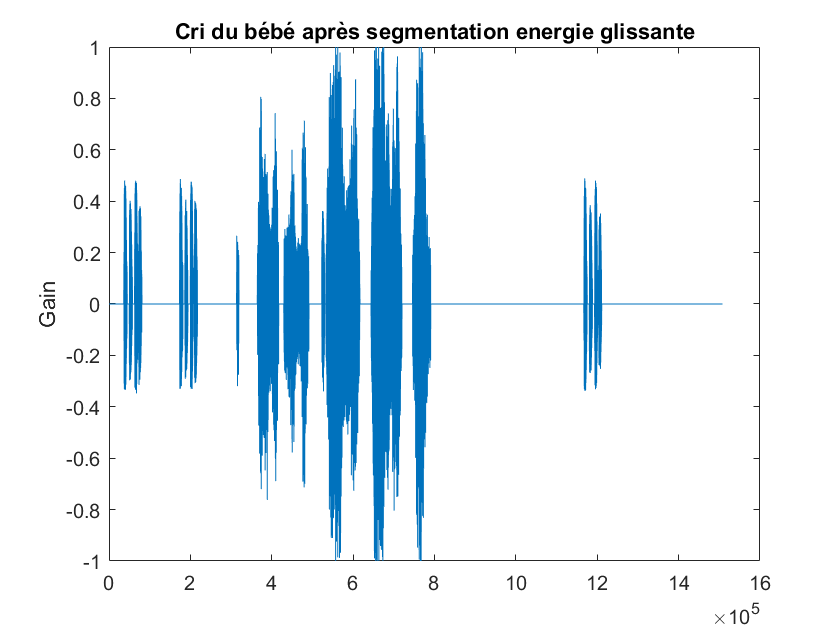

audiowrite("signal_sortie_segmentation_energie_glissante.wav", signal_sortie_segmentation_energie_glissante, FS)
subplot(1, 1, 1); plot(signal_sortie_segmentation_energie_glissante); 
ylabel("Gain");
title("Cri du bébé après segmentation energie glissante");

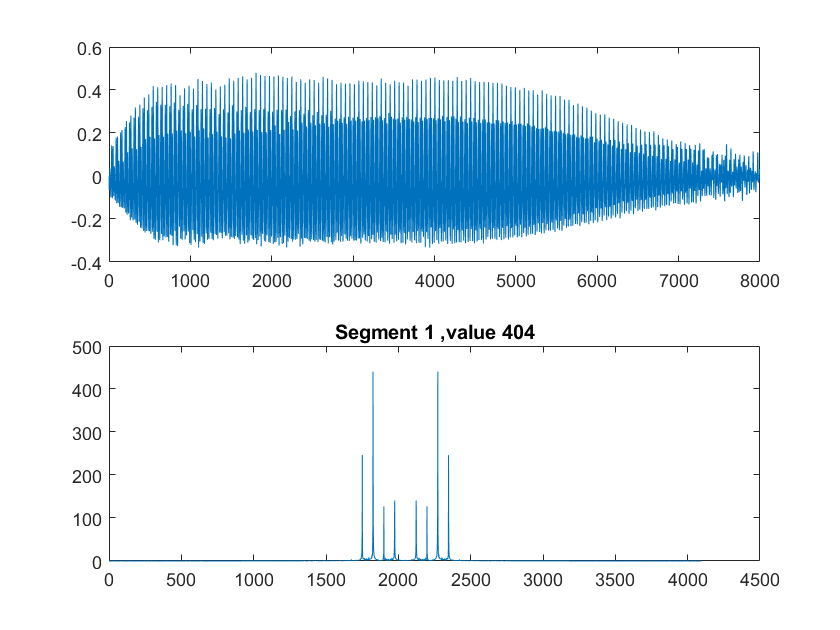

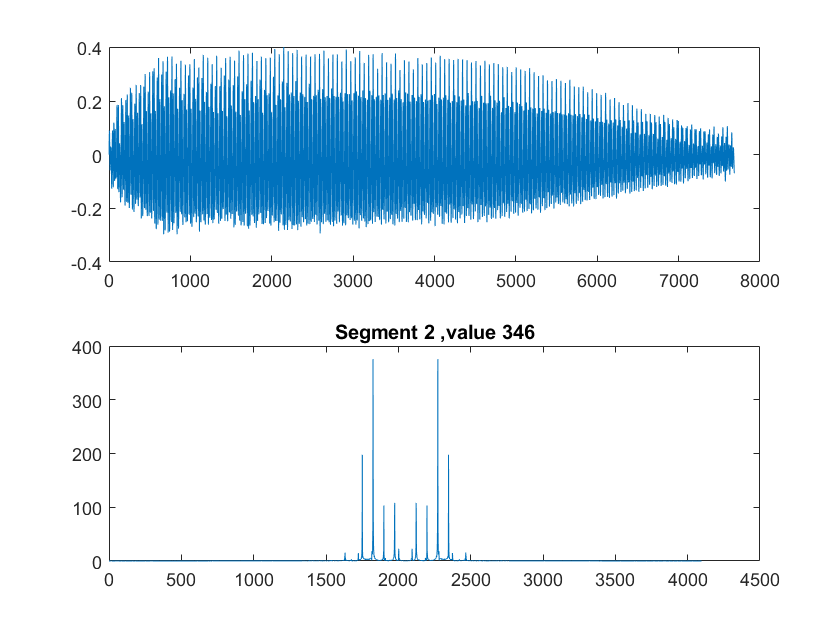

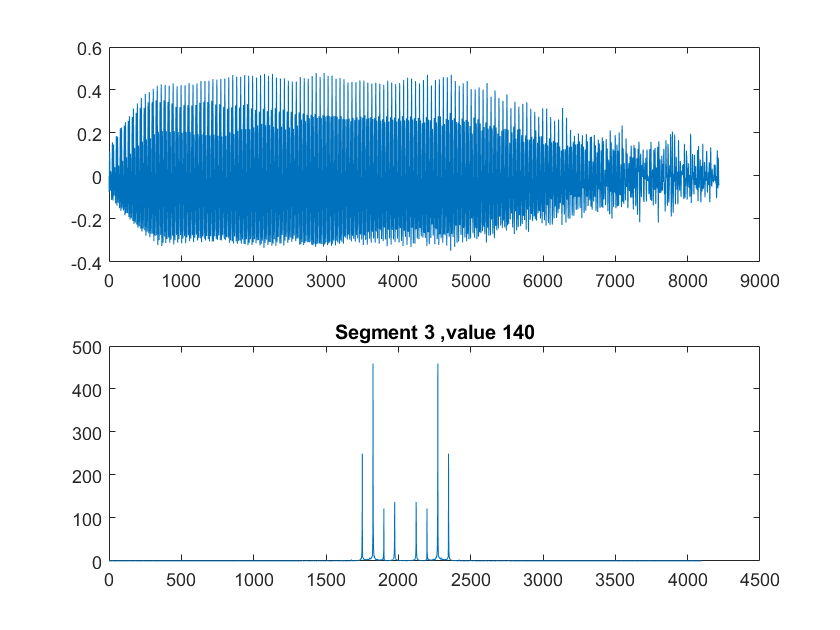

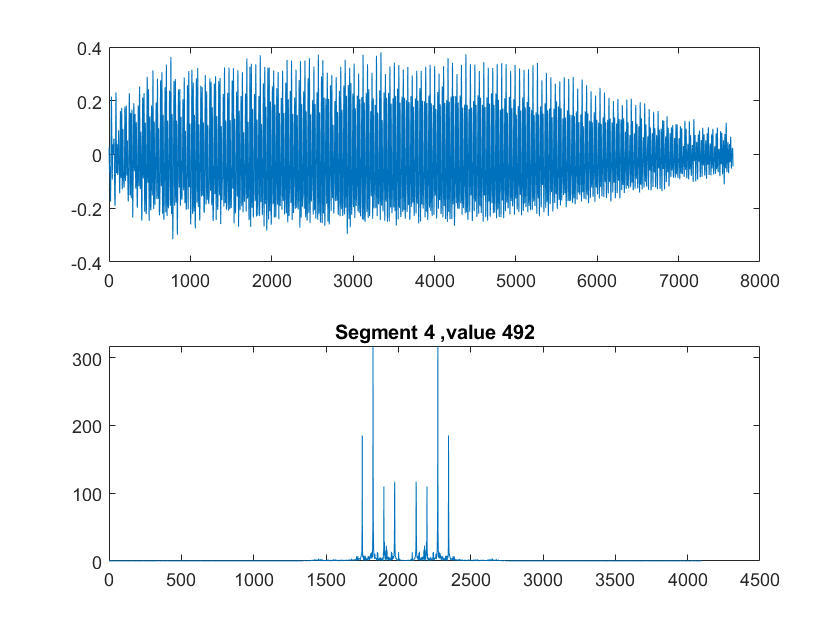

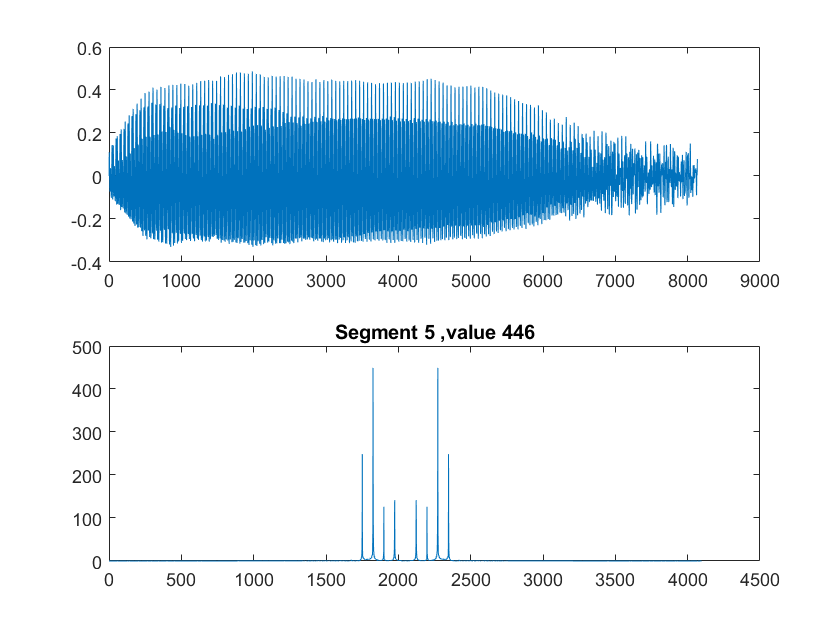

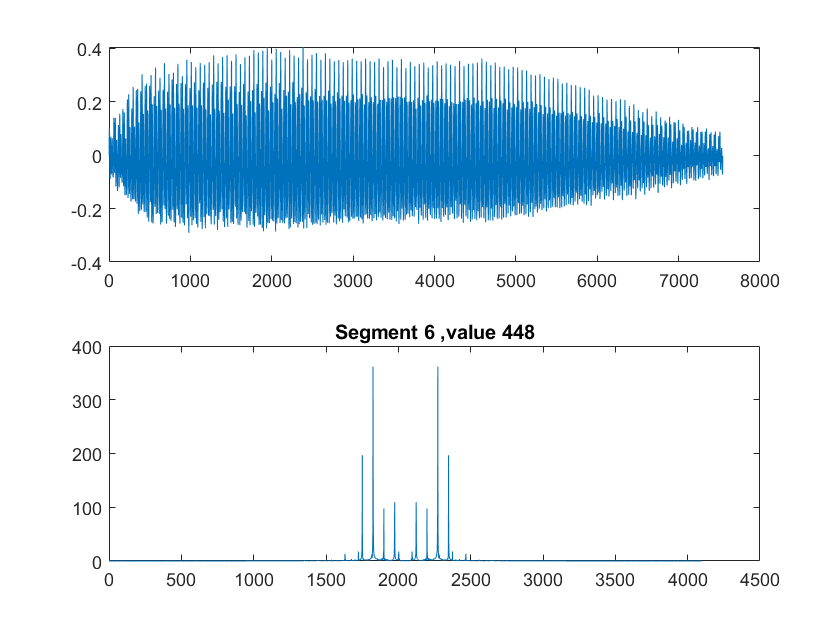

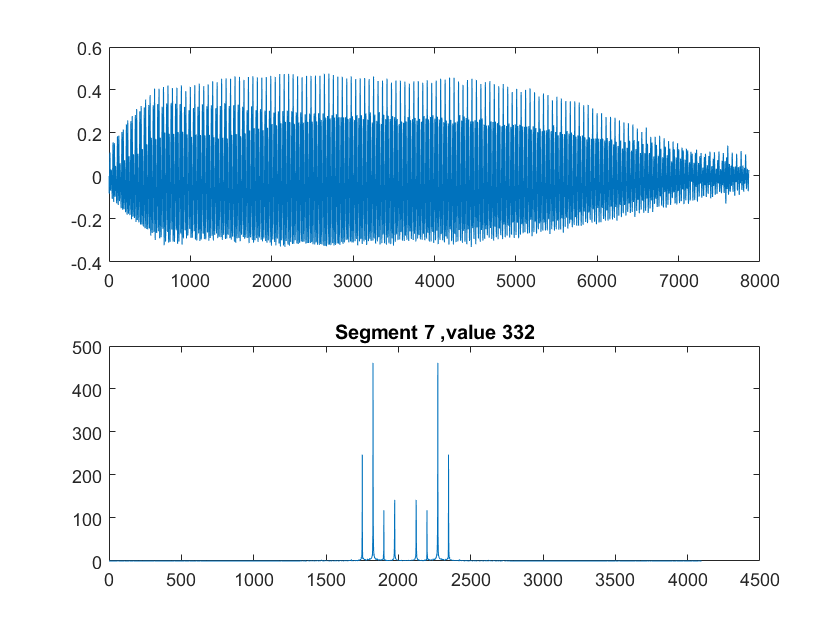

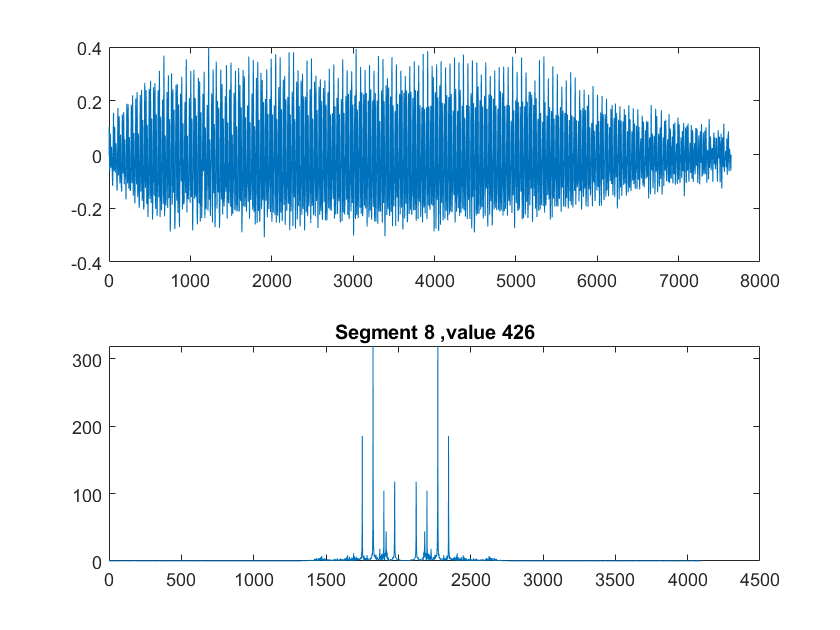

[signal_sortie_segmentation_fft, mean_length] = segmentation_fft(signal_sortie_segmentation_energie_glissante, vecteur_logique, FS);

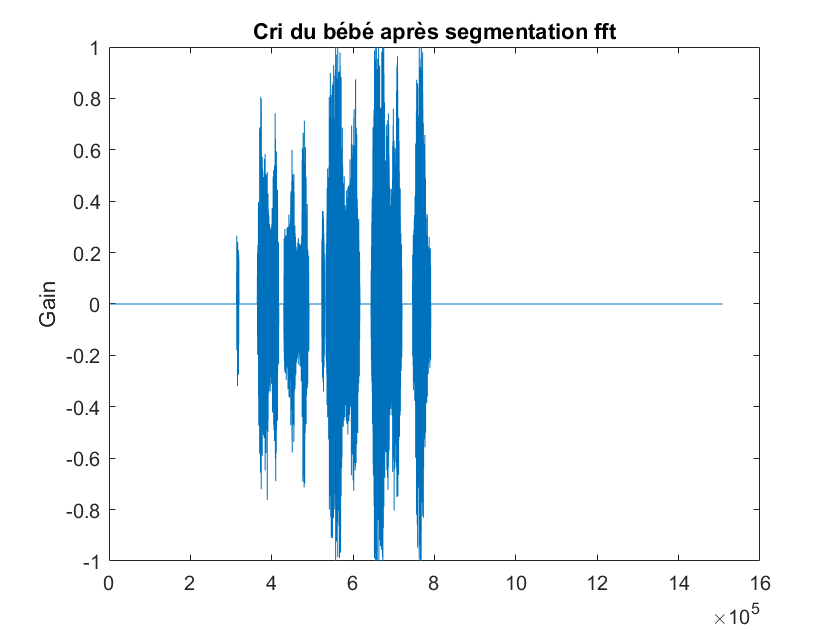

audiowrite("signal_sortie_segmentation_fft.wav", signal_sortie_segmentation_fft, FS)
subplot(1, 1, 1); plot(signal_sortie_segmentation_fft); 
ylabel("Gain");
title("Cri du bébé après segmentation fft");

mean_length

mean_length = 1.1951